%PIECE WISE CONSTANT TREND IDENTIFICATION 
clear variables;

data = load("product_5.mat");

id = struct("t",data.time(1:79),"y",data.y(1:79));
val = struct("t",data.time(80:99),"y",data.y(80:99));

m = 6;
P = 12; % default period

%identification data
phi = zeros(length(id.y),2+2*m);
for line = 1:length(id.t) 
    phi(line,1) = 1;
    phi(line,2) = id.t(line);
    for regressor = 1:m
        phi(line,1+2*regressor) = cos(2*pi*regressor*id.t(line)/P);
        phi(line,2+2*regressor) = sin(2*pi*regressor*id.t(line)/P);
    end
end

phi

phi =     1.0000    1.0000    0.8660    0.5000    0.5000    0.8660    0.0000    1.0000   -0.5000    0.8660   -0.8660    0.5000   -1.0000    0.0000
    1.0000    2.0000    0.5000    0.8660   -0.5000    0.8660   -1.0000    0.0000   -0.5000   -0.8660    0.5000   -0.8660    1.0000   -0.0000
    1.0000    3.0000    0.0000    1.0000   -1.0000    0.0000   -0.0000   -1.0000    1.0000   -0.0000    0.0000    1.0000   -1.0000    0.0000
    1.0000    4.0000   -0.5000    0.8660   -0.5000   -0.8660    1.0000   -0.0000   -0.5000    0.8660   -0.5000   -0.8660    1.0000   -0.0000
    1.0000    5.0000   -0.8660    0.5000    0.5000   -0.8660    0.0000    1.0000   -0.5000   -0.8660    0.8660    0.5000   -1.0000    0.0000
    1.0000    6.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000   -0.0000
    1.0000    7.0000   -0.8660   -0.5000    0.5000    0.8660   -0.0000   -1.0000   -0.5000    0.8660    0.8660   -0.5000   -1.0000    0.0000
    1.0


y = id.y

y = 	1.0e+03 *

    0.0100
    0.6810
    0.9690
    1.2880
    1.3370
    1.4960
    1.4540
    0.9860
    3.0868
    3.2640


theta = phi\y

theta = 	1.0e+03 *

    2.0185
    0.0307
    1.5661
   -0.2192
    0.5396
    0.1110
    0.3321
    0.1162
    0.0806
    0.0036


y_hat = phi*theta

y_hat = 	1.0e+03 *

    3.6222
    2.2493
    1.2263
    1.1186
    1.0147
    0.7867
    1.3846
    1.5935
    2.3278
    2.4751


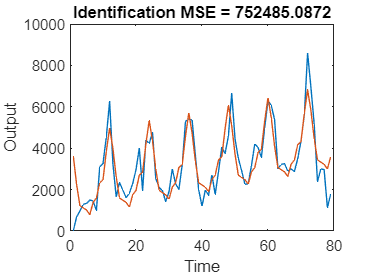


mse = 1/length(id.t)*sum((y_hat-y).^2);

plot(id.t,id.y,id.t,y_hat); title("Identification MSE = " + string(mse));
xlabel("Time"); ylabel("Output");

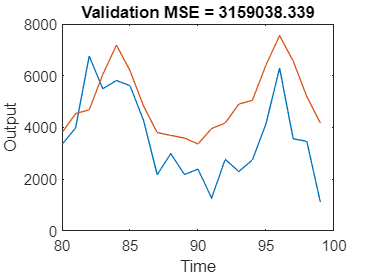


%validation data 

phi = zeros(length(val.y),2+2*m);
for line = 1:length(val.t) 
    phi(line,1) = 1;
    phi(line,2) = val.t(line);
    for regressor = 1:m
        phi(line,1+2*regressor) = cos(2*pi*regressor*val.t(line)/P);
        phi(line,2+2*regressor) = sin(2*pi*regressor*val.t(line)/P);
    end
end


y = val.y;
y_hat = phi*theta;

% YHAT DIFERA MULT DE Y

mse = 1/length(val.t)*sum((y_hat-y).^2);

plot(val.t,val.y,val.t,y_hat); title("Validation MSE = " + string(mse));
xlabel("Time"); ylabel("Output");